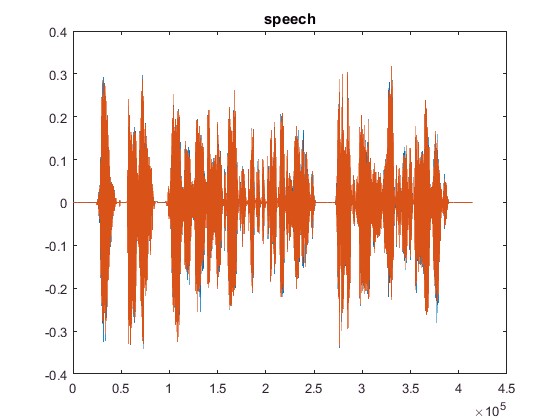

[speech , fs]=audioread('joey.wav') ;
plot(speech),title ('speech') 

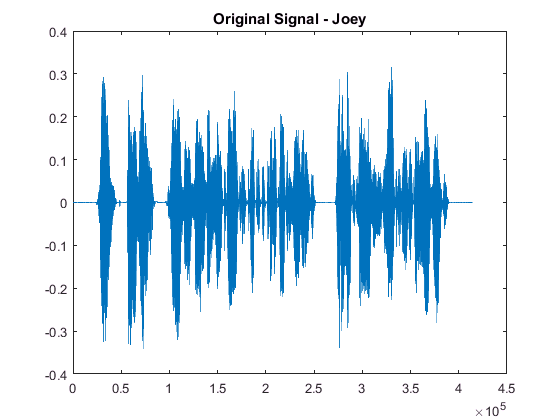

speech1=speech(:,1);
sound(speech1,fs);
plot(speech1),title('Original Signal - Joey')

fd=0.050;
fsize=round(fd*fs);
s=zeros(fsize+1,175);

for j=1:175
 s(:,j)=speech1(  10000+(fsize.*(j-1)) :  10000+ (fsize.*j) )';
end 

j=1;
noise1=(0.02).*randn(400000,1);
noise=zeros(fsize+1,175);
for j=1:175
    noise(:,j)=noise1(  10000+(fsize.*(j-1)) :  10000+ (fsize.*j) )';   
end
%noise=(0.02).*randn(2206,175);
%[noise1,fs]=audioread('WGN.wav');
%noise1;
%noise=zeros(fsize+1,175);
%for j=1:175
 %noise(:,j)=noise1(  10000+(fsize.*(j-1)) :  10000+ (fsize.*j) )';
%end 
%noise

sum_noise=0;
j=1;k=1;
for j=1:175
    for k=1:2206
        sum_noise = sum_noise + noise(k,j);
    end
end
sum_noise

sum_noise = 3.1899

j=1;k=1;
for j=1:175
    for k=1:2206
        s(k,j) = s(k,j) +  noise(k,j);
    end
end

for l=1:175
    p( ((2206.*l)+ 1): (2206.*(l+1) ) , 1)= s(:,l);
end
p

p =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


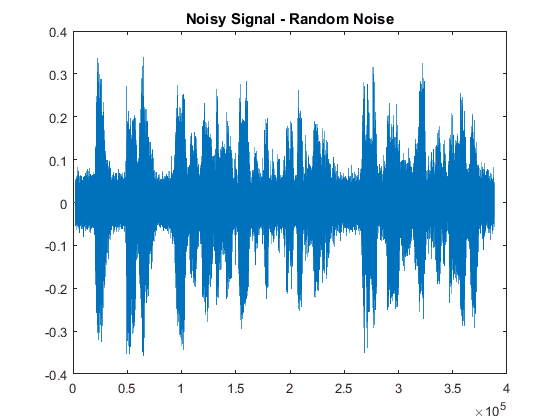

sound(p,fs)
plot(p),title('Noisy Signal - Random Noise')

j=1;k=1;
for j=1:175
    for k=1:2206
        y_fft(k,j)= fft(s(k,j));
        d_fft(k,j)=fft(noise(k,j));
    end
end

j=1;k=1;
for j=1:175
    for k=1:2206
       phase(k,j)=angle(y_fft(k,j));
       mag_y(k,j)=abs(y_fft(k,j));
       mag_d(k,j)=abs(d_fft(k,j));
    end
end

Y = mag_y.*mag_y;
D = mag_d.*mag_d;

sum_Y=0;
sum_D=0;
j=1;k=1;
for j=1:1753
    for k=1:2206
        sum_Y=sum_Y + Y(k,j);
        sum_D=sum_D + D(k,j);
    end
end
sum_Y

sum_Y = 1.3657e+03

sum_D

sum_D = 154.3081

snr=(sum_Y/sum_D)

snr = 8.8502

snr=20.*log10(snr)

snr = 18.9390

snr_diff=20

snr_diff = 20

alpha = 4- (3/20).*(snr)

alpha = 1.1591

beta=0.00040

beta = 4.0000e-04

c= 1 ./(alpha+ beta)

c = 0.8624

S=zeros(2206,175);
j=1;k=1;
for j=1:175
    for k=1:2206
    if( (D(k,j)/Y(k,j)) < c)
        S(k,j) =( Y(k,j) - alpha.*D(k,j));
    else
        S(k,j) = beta.*D(k,j);
    end
    end
end

j=1;k=1;
for j=1:175
    for k=1:2206
        S(k,j)=sqrt(S(k,j));
    end
end
i=sqrt(-1)

i =    0.0000 + 1.0000i


j=1;k=1;
for j=1:175
    for k=1:2206
        S(k,j)=ifft( S(k,j).*(exp(i*phase(k,j))) , 'symmetric');
    end
end

for l=1:175
    req( ((2206.*l)+ 1): (2206.*(l+1) ) , 1)= S(:,l);
end
req

req =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


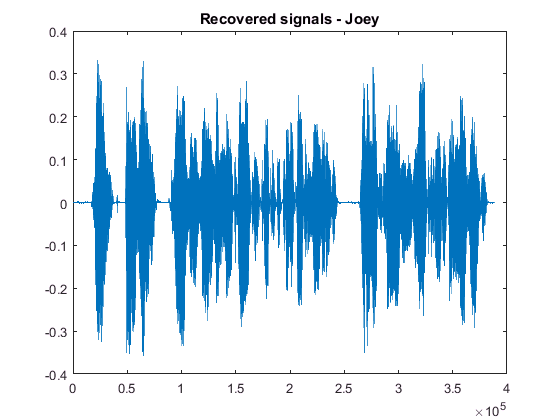

sound(req,fs)
plot(req),title('Recovered signals - Joey')